# Analysis of social, multi-flavor experiment on 2/10/2024

## Data import

#### Root directory

rootdir = 'Z:\users\Tatsumi\data\MultiReward\multibat\240207';
ephys_rootdir = 'Z:\users\Tatsumi\data\MultiReward\multibat\240207\ephys\20240207_103632.rec'; % the root directory of all merged rec files
cd(rootdir)

### Subdirectory

% preprocessing
% run PreprocessAllEphys.m
% run PreprocessBhvData.m

% output directory
analysis_dirpath     =   fullfile(rootdir,'analysis');
% Figure
fig_dirpath    =   fullfile(analysis_dirpath,'figure');

### Experiment info

mtData.rec_date = '240210_2'; % recording date
mtData.rec_type = 'untethered'; % recording type
mtData.exp_type = 'social,multi-flavor'; % experiment type

% Bat subjects
mtData.bname = {"14447","11827","29924","14406","14561","14633","14662","14531","71050","9776"}; % in order of serial number list
mtData.bname_ephys = {'14633','14662'}; % ephys bat

% reward
mtData.reward_list = {"banana","pear","grape","melon"};
mtData.reward_session = [1,1,0,0; 1,1,0,0];
save(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')

### Preprocess and load behavioral data

[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


Final MinPeakDistance was 0.5 
322 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


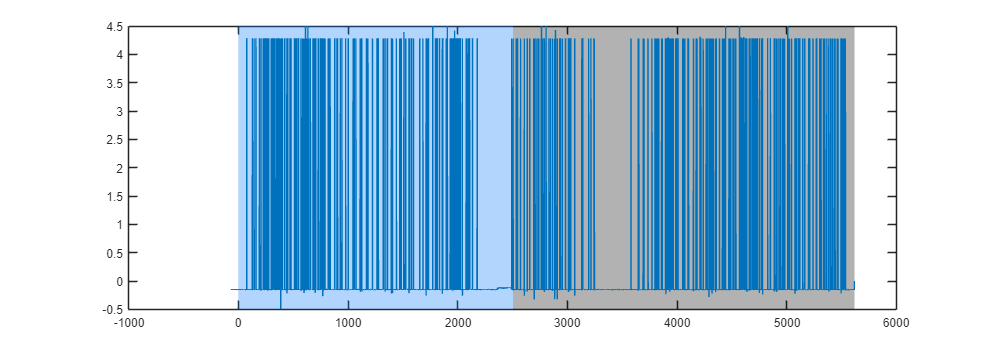

RewardData = PreprocessRewardData(rootdir);

#### Check the time alignment across different data

% camera
FdCamDir = dir(fullfile(rootdir,'camera','feeder13','*.mp4'));
FdCamDir = fullfile(FdCamDir.folder, FdCamDir.name);
% FdCamDir = dir(fullfile(rootdir,'camera','feeder24','*.mp4'));
% FdCamDir = fullfile(FdCamDir.folder, FdCamDir.name);


1th bat: 147 landing were detected. 
2th bat: 52 landing were detected. 
3th bat: 104 landing were detected. 
4th bat: 196 landing were detected. 
5th bat: 182 landing were detected. 
6th bat: 117 landing were detected. 
7th bat: 68 landing were detected. 
8th bat: 163 landing were detected. 
9th bat: 181 landing were detected. 
10th bat: 83 landing were detected. 


%  create a video object
vidObj = VideoReader(FdCamDir); % Video object for feeder 13
fs_cam = vidObj.FrameRate; % Frame rate
n_frame = vidObj.NumFrames; % number of frames
t_camera = ((0:n_frame-1)/fs_cam)'; % time stamps: t=0 is set at the first 3-sec TTL
t_camera = t_camera(1:90:end);


1th bat: 32 landing were detected. 
2th bat: 11 landing were detected. 
3th bat: 22 landing were detected. 
4th bat: 47 landing were detected. 
5th bat: 65 landing were detected. 
6th bat: 36 landing were detected. 
7th bat: 22 landing were detected. 
8th bat: 71 landing were detected. 
9th bat: 77 landing were detected. 
10th bat: 38 landing were detected. 


% Analog Signals
[~,locs] = findpeaks(AnalogData.signals(:,2),"MinPeakHeight",4,"MinPeakDistance",10);
t_analog_3sec = AnalogData.signals(locs,4);

[~,locs] = findpeaks(AnalogData.signals(:,3),"MinPeakHeight",2,"MinPeakDistance",10);
t_analog_fib = AnalogData.signals(locs,5);
TTL_time_diff = [21; 13; 8; 5; 3];  %TTL delays in s
TTL_abs_times = [0; cumsum(repmat(TTL_time_diff,400,1))];
TTL_abs_times = TTL_abs_times(1:length(t_analog_fib)) + 1.05;

figure;
plot(t_camera,t_analog_3sec,'k')
hold on
plot(TTL_abs_times,t_analog_fib,'b')
plot([0,6000],[0,6000],'r')
hold off

## Reconstruction of probe

% make directory for figures

22 clusters for bat 1 are detected. 
11 clusters for bat 2 are detected. 
16 clusters for bat 3 are detected. 
35 clusters for bat 4 are detected. 
19 clusters for bat 5 are detected. 
11 clusters for bat 6 are detected. 
10 clusters for bat 7 are detected. 
9 clusters for bat 8 are detected. 
23 clusters for bat 9 are detected. 
12 clusters for bat 10 are detected. 


figDir = fullfile(rootdir,'analysis','figure','ProbeReconstruction');
if isempty(dir(figDir))
    mkdir(figDir)
end

### Bat # 14662

batid = '14662'; % id of bat
ephysDir = dir(fullfile(ephys_rootdir,batid,'Processed')); ephysDir = ephysDir(1).folder;
lfpData = loadTrodesLFP(ephysDir);

#### dCA1_vCA1_3

% 14662: dCA1_MEC_2
probeNum = 1; % probe number
spikeData = loadSpikeData(ephysDir,'kilosort_out_folder_name', sprintf('kilosort_outdir_probe%d',probeNum));

% LFP correlation and spectrogram
generateLFPplots(lfpData,batid,probeNum)

% spike rasterplot without layer information
generateRasterPlotNP(spikeData)

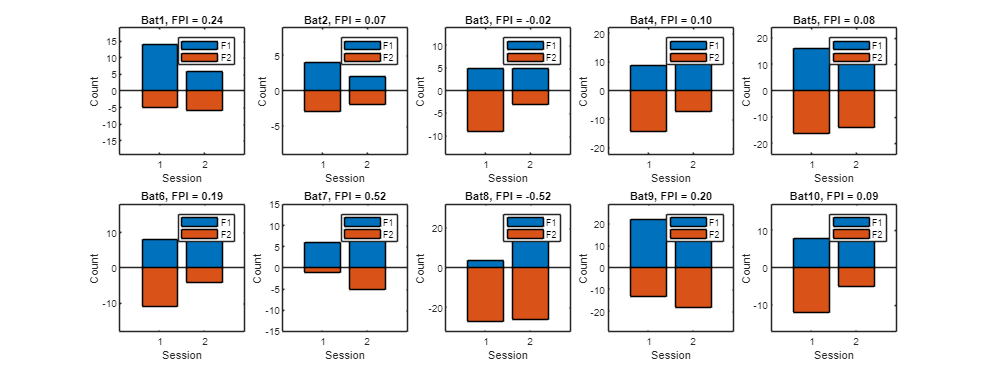

% Specify the layer information
layers = struct([]);
layers(1).name = 'CA1';
layers(1).depth =[0,1700];

layers(2).name = 'CA3';

layers(2).depth = [1700, 3300];

layers(3).name = 'CA1';
layers(3).depth =[3300,4100];

% layers(4).name = 'VC';
% layers(4).depth =[6000,8000];

% Regenerate the spike rasterplot
generateRasterPlotNP(spikeData,'layers',layers)
saveas(gcf,fullfile(figDir,sprintf('Rasterplot_bat%s_probe%d.jpg',batid,probeNum)))

## Data Visualization

### Detect takeoff/landings based on the cdp data

Extract the start/end timings and the position of all the landings/flights. The extracted information is saved into `Landings/Flights`

Landings = extractLandings(BhvData,RewardData,'include','all');
for bb = 1:length(Landings)
    n_land = Landings(bb).n_land;
    fprintf('%dth bat: %d landing were detected. \n',bb, n_land)
end

% feeder landings
Landings_fd = extractLandings(BhvData,RewardData,'include','feeder');
for bb = 1:length(Landings_fd)
    n_land = Landings_fd(bb).n_land;
    fprintf('%dth bat: %d landing were detected. \n',bb, n_land)
end

#### Visualize all the landings

figDir = fullfile(rootdir,'analysis','figure','AllLandingTrajectory');
PlotAllFlightTraj(BhvData,RewardData,figDir)

#### Visualize the landings on the feeders

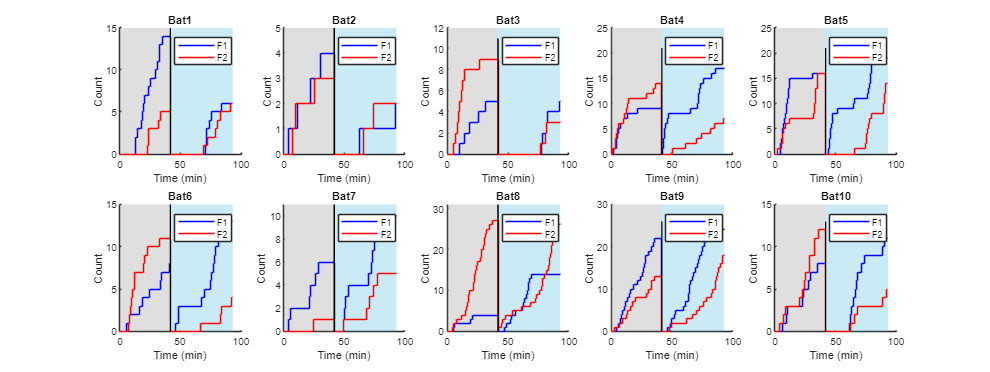

figDir = fullfile(rootdir,'analysis','figure','AllFeederLandingTrajectory');

PlotAllFlightTraj(BhvData,RewardData,figDir,'include','feeder')

#### Clustering the flight trajectories

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


Final MinPeakDistance was 0.5 
322 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


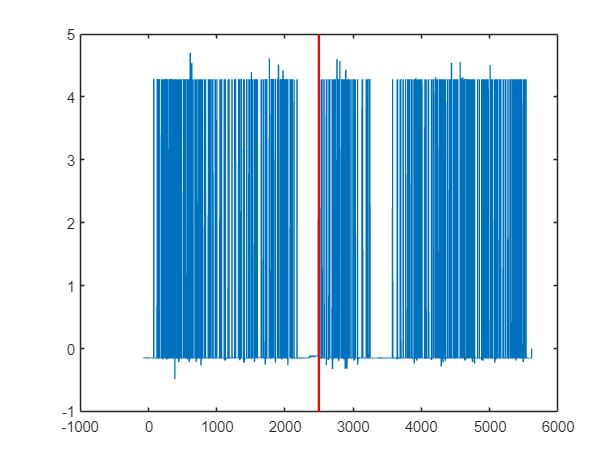

1th bat: 147 landing was detected from the cdp data. 
2th bat: 52 landing was detected from the cdp data. 
3th bat: 104 landing was detected from the cdp data. 
4th bat: 196 landing was detected from the cdp data. 
5th bat: 182 landing was detected from the cdp data. 
6th bat: 117 landing was detected from the cdp data. 
7th bat: 68 landing was detected from the cdp data. 
8th bat: 163 landing was detected from the cdp data. 
9th bat: 181 landing was detected from the cdp data. 
10th bat: 83 landing was detected from the cdp data. 


% Hierarchical clustering of trajectories
% hc = TrajClusteringHC(Landings,'cutoff',1,'minpts',2,'n_smp',50,'n_dim',3);
% FigDir = fullfile(pwd,'analysis','figure','ClusteredTrajectory_HC');
% PlotClusteredTrajectory(TrjCluster,'FigDir',FigDir)

% DBSCAN clustering of trajectories
TrjCluster = TrajClusteringDBSCAN(Landings,'minpts',2,'n_smp',100,'n_dim',2);

FigDir = fullfile(pwd,'analysis','figure','ClusteredTrajectory_DBSCAN');
PlotClusteredTrajectory(TrjCluster,'FigDir',FigDir)

### Feeder/reward preference based on the cdp data

Feeder preference

% Load data
Landings_fd = extractLandings(BhvData,RewardData,'include','feeder'); % landings
n_session = size(mtData.reward_session,1); % number of sessions
n_bats = length(mtData.bname); % number of bats
n_feeder = 2; % number of feeders

%%% FIGURE: feeder preference
fig = figure;
fontsize(fig, 24, "points")
set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
for bb = 1:n_bats   
    % Compute preference for feeder and/or reward. 
    % Feeder/reward preference index (PI), defined as (|F1-F2|/|F1+F2|) where F1 or F2 is the counts of landings on the feeder 1 or feeder 2.
    % The range is -1 < PI < 1. The larger PI means that the bat prefers to the feeder 1, while the lower PI means that the bat does the feeder 2.
    % PI = 0 means that there is no preference.

    % Feeder preference
    X = Landings_fd(bb).session_land;
    Y = Landings_fd(bb).closest_feeder(:,2);
    [feeder_pref, feeder_pref_index] = computePreferenceIndex(X,Y,n_session,n_feeder);

    feeder_pref(:,2) = feeder_pref(:,2)*-1;

    % reward_pref = zeros(n_session,2);
    % feeder_pref = zeros(n_session,2);
    % for ss = 1:n_session
    %     for ff = 1:2 % number of active feeder
    %         feeder_pref(ss,ff) = sum(Landings_fd(bb).session_land==ss & Landings_fd(bb).closest_feeder(:,2)==ff);
    %     end
    % 
    %     for flavor = 1:2 % number of flavor types
    %         reward_pref(ss,flavor) = sum(Landings_fd(bb).session_land == ss & Landings_fd(bb).reward == flavor);
    %     end
    % end
    % feeder_pref(:,2) = feeder_pref(:,2)*-1;
    % reward_pref(:,2) = reward_pref(:,2)*-1;
    
    % Feeder/reward preference index (PI), defined as (|F1-F2|/|F1+F2|) where F1 or F2 is the counts of landings on the feeder 1 or feeder 2.
    % The range is -1 < PI < 1. 
    % The larger PI means that the bat prefers to the feeder 1, while the
    % lower PI means that the bat does the feeder 2. PI = 0 means that
    % there is no preference
    % feeder_pref_index = -1*diff(abs(feeder_pref),1,2)./sum(abs(feeder_pref),2); 
    % reward_pref_index = -1*diff(abs(reward_pref),1,2)./sum(abs(reward_pref),2); 

    max_cnt = max(max(abs(feeder_pref)));

    % FIGURE
    nexttile
    bar(categorical(1:n_session),feeder_pref,'stacked')
    title(sprintf('Bat%s, FPI = %.2f',num2str(bb),mean(feeder_pref_index,'omitnan')))
    xlabel('Session')
    ylabel('Count')
    legend({"F1","F2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end
% Figure directory
FigDir = fullfile(fig_dirpath,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(fig,fullfile(FigDir,'Feeder_preference_cdp.png'))

#### Cumulative preference plot

Cumulative plot for the feeder preference

Landings_fd = extractLandings(BhvData,RewardData,'include','feeder'); % landings
t_session = RewardData.t_session_sec; % time of the start of sessions in sec
t = BhvData.t; % timestamps for behavior data
n_session = size(mtData.reward_session,1); % number of sessions
n_bats = length(mtData.bname); % number of bats

%%% FIGURE: cumulative plot of feeder landings
fig = figure;
fontsize(fig, 24, "points")
set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
fig_clr = {'b','r'};
for bb = 1:n_bats
    nexttile
    hold on
    for ff = 1:2 % number of active feeder
        
        t_rw_cum_sec = []; % time of reward delivery in sec
        reward_cum = []; % cumulative count of reward delivery
        
        for ss = 1:n_session
            t_rw_cum_sec = [t_rw_cum_sec; t_session(ss)];
            reward_cum = [reward_cum; 0];
            
            idx = Landings_fd(bb).closest_feeder(:,2)==ff & Landings_fd(bb).session_land == ss; % index for the current feeder
            t_rw_cum_sec = [t_rw_cum_sec; Landings_fd(bb).t_land_sec(idx)];
            reward_cum = [reward_cum;cumsum(ones(sum(idx),1))];
        end
        t_rw_cum_sec = [t_rw_cum_sec; t(end)];
        t_rw_cum_min = t_rw_cum_sec / 60; % convert to minutes
        reward_cum = [reward_cum; reward_cum(end)];
    
        stairs(t_rw_cum_min,reward_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (min)')
    ylabel('Count')
    
    % Draw the boundary of session
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss)/60,t_session(ss)/60],[y_lim(1),y_lim(2)+1],'k')
    end

    for session = 1:n_session
        if mod(session,2) == 0
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[80,190,225]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[80,190,225]/255)
            end
        else
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[150,150,150]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[150,150,150]/255)
            end
        end
    end

    hold off

    f=get(gca,'Children');
    legend([f(length(f)),f(length(f)-1)],'F1','F2')
end

% Figure directory
FigDir = fullfile(fig_dirpath,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(gcf,fullfile(FigDir,'Cumulative_feeder_preference_cdp.png'))

### Spike activity during flight

### Single units

#### Aligning the behavioral and neural data

% Load data
Landings = extractLandings(BhvData,RewardData,'include','all'); % landings
TrjCluster = TrajClusteringDBSCAN(Landings,'minpts',2,'n_smp',100,'n_dim',2); % clustered trajectory by DBSCAN
batid = '14662'; % id of bat
ephysDir = dir(fullfile(ephys_rootdir,batid,'Processed')); ephysDir = ephysDir(1).folder;
probeNum = 1; % probe number
spikeData = loadSpikeData(ephysDir,'kilosort_out_folder_name', sprintf('kilosort_outdir_probe%d',probeNum)); % Load spike data
% Align spike and behavioral data
sp = extractSpikeDuringBehavior(spikeData,Landings,TrjCluster,mtData,'su');

#### Raster plot for each cluster of self flight

Spike activity during the flight of 14662 itself

bat_idx = 6; % a vector of bat index to be plotted
FigDir = fullfile(rootdir,'analysis','figure','RasterPlot_SU_flight');
RasterPlot_clusteredFlights(sp,bat_idx, FigDir)

#### Raster plot for flights for each feeders

bat_idx = 6; % a vector of bat index to be plotted
ephys_bat = '14662';
% bhv_types = {'flight','landing'}; % behavior types to plot
bhv_types = {'landing'}; % behavior types to plot

RasterPlot_unclusteredBehavior(sp,ephys_bat,bat_idx,bhv_types)

#### Raster plot during the landings before the flights to the feeders

bat_idx = 6; % a vector of bat index to be plotted
ephys_bat = '14662';
% bhv_types = {'flight','landing'}; % behavior types to plot
% bhv_types = {'landing'}; % behavior types to plot

RasterPlot_previousLandings(sp,ephys_bat,bat_idx)

## Video analysis

#### Extract video while landing on the feeders

FdCamDir = dir(fullfile(rootdir,'camera','feeder13','*.mp4'));
FdCamDir = fullfile(FdCamDir.folder, FdCamDir.name);


FdCamDir = dir(fullfile(rootdir,'camera','feeder24','*.mp4'));
FdCamDir = fullfile(FdCamDir.folder, FdCamDir.name);

%  create a video object
vidObj = VideoReader(FdCamDir); % Video object for feeder 13
fs_cam = vidObj.FrameRate; % Frame rate
n_frame = vidObj.NumFrames; % number of frames
t_camera = ((0:n_frame-1)/fs_cam)'; % time stamps: t=0 is set at the first 3-sec TTL

## Visualize all landing

Compare the number of detected landings between the cdp and the reward delivery data.

% th_d_fd = 0.2; % threshold of the distance from feeders
% for bb = 1:n_tags
%     r_land_med = Landings_fd{bb,5};
%     n_land = Landings_fd{bb,3};
% 
%     is_land_f1 = Landings_fd{bb,10}(:,2)==1;
%     is_land_f2 = Landings_fd{bb,10}(:,2)==2;
%     d_land_f1 = Landings_fd{bb,10}(is_land_f1,1);
%     d_land_f2 = Landings_fd{bb,10}(is_land_f2,1);
%     is_land_anyf = any([is_land_f1,is_land_f2],2);
%     fprintf('Bat%d landings on feeder: cdp %d, analog %d\n',bb,sum(is_land_anyf),sum(reward(:,9)==bb))
% end
